**1.** Take a look to your RNAseq counts dataset.

rnaseq_data_path = 'data/Saccharomyces_RNAseq_RAW_counts.csv';
rnaseq_table = readtable(rnaseq_data_path);

**a)** How many genes are represented in your dataset? 

disp(length(rnaseq_table.GeneName));

        7126



**b) **How many biological replicates per experimental conditions were obtained in this study? 

We start by having a look at the column headers:

disp(rnaseq_table.Properties.VariableNames);

    'GeneName'    'Control_Rep1'    'Control_Rep2'    'Control_Rep3'    'HighTemperature_Rep1'    'HighTemperature_Rep2'    'HighTemperature_Rep3'    'LowPH_Rep1'    'LowPH_Rep2'    'LowPH_Rep3'    'OsmoPressure_Rep1'    'OsmoPressure_Rep2'    'OsmoPressure_Rep3'    'Anaerobic_Rep1'    'Anaerobic_Rep2'    'Anaerobic_Rep3'



There are 16 columns, with one being `GeneName`. Looking at the remaining 15 columns, they end with `1, 2, 3`. This indicates **3** biological replicates per experimental condition.

**c)** How many genes were actually measured by RNAseq (non-zero reads)?

rnaseq_array = table2array(rnaseq_table(:,vartype('numeric')));
nonzero_rnaseq_array = rnaseq_array(all(rnaseq_array, 2),:);
disp(nnz(all(nonzero_rnaseq_array, 2)));

        5950



**d)** Normalize your read counts dataset, by first dividing the values by the mean expression level of each gene across samples, and then dividing each library (column) by the median of its previously normalized values.

normalized_array = nonzero_rnaseq_array./median(nonzero_rnaseq_array./geomean(nonzero_rnaseq_array, 2),1);

**e)** Visualize your read counts distributions using boxplots for the transformed log2 values (before and after normalization). What can you say about your dataset in terms of spanning (orders of magnitude), median expression values? **Are there any evident effects on the dataset with the proposed normalization method? If so, try to explain them.**

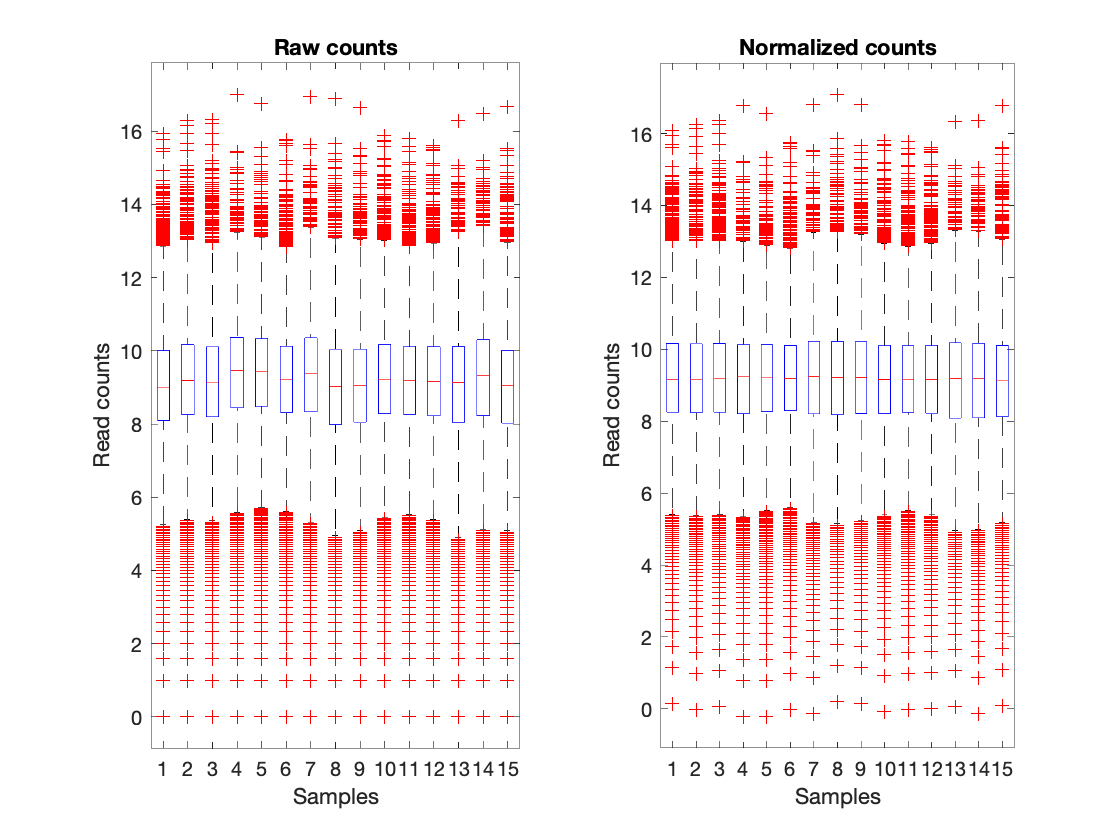

figure
% generate boxplot for log2 raw read counts
subplot(1,2,1);
boxplot(log2(nonzero_rnaseq_array))
title('Raw counts'); ylabel('Read counts'); xlabel('Samples');
% generate boxplot for log2 normalized counts
subplot(1,2,2);
boxplot(log2(normalized_array))
title('Normalized counts'); ylabel('Read counts'); xlabel('Samples');

The orders of magnitude have remained the same. The median values, however, are much more aligned.

**As about plotting nonzero values, they are plotted in the exercise.**

**2.** Show your PCA results (PC1 vs PC2, displaying the percentage of variance for each in their respective axis labels).

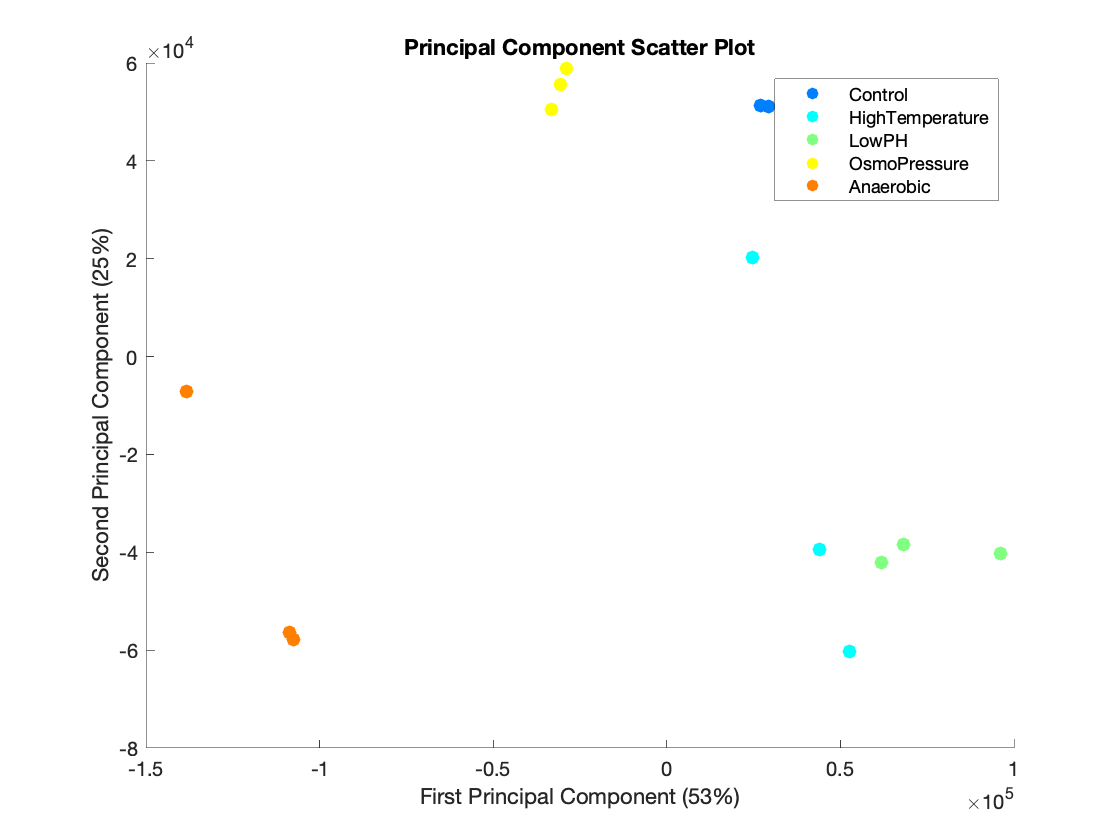

% perform PCA
[pc, zscores, pcvars] = pca(normalized_array');
% pick 5 colors to distinguish the 5 different conditions. Colormap returns
% the a mapped normalized RGB values for the specified amount of colorlevels
% in a given palette (jet in this case)
figure
colorScheme = colormap(jet(5));
hold on
% get a PCA plot showing PC1 and PC2 for all the samples in the 5 conditions
% Note: PC's are stored in the zscores table in which for each sample (columns) 
% the 15 first principal components are shown (rows).
condStr = {};
for i=1:5
    % get the condition name
    nameTMP = strsplit(rnaseq_table.Properties.VariableNames{(i-1)*3+2},'_');
    PC1     = zscores((i-1)*3+1:i*3,1);
    PC2     = zscores((i-1)*3+1:i*3,2);
    condStr = [condStr;nameTMP{1}];
    scatter(PC1,PC2,50,colorScheme(i,:),'fill');
end
pc1var = round(pcvars(1)/sum(pcvars)*100);
pc2var = round(pcvars(2)/sum(pcvars)*100);
xlabel(['First Principal Component (', num2str(pc1var), '%)']); 
ylabel(['Second Principal Component (', num2str(pc2var), '%)']);
title('Principal Component Scatter Plot');
legend(condStr)
hold off

**a)** Explain what the PCA results show.

The PCA plot shows how the different samples compare to each other in terms of overall similarity across the expression of all genes.

**b)** Are there any outlier samples in the dataset for any of the analyzed conditions?

One of the anaerobic samples appears much different than the other two. Moreover, the gene expression values vary between the high temperature samples (far apart in the plot).

**3.** Show the number of differentially expressed genes reference and a stress condition of your choice (High temperature, low pH, osmotic pressure). **Use absolute log2 fold-change = 2 and 0.01 corrected p-value as your threshold parameters.**

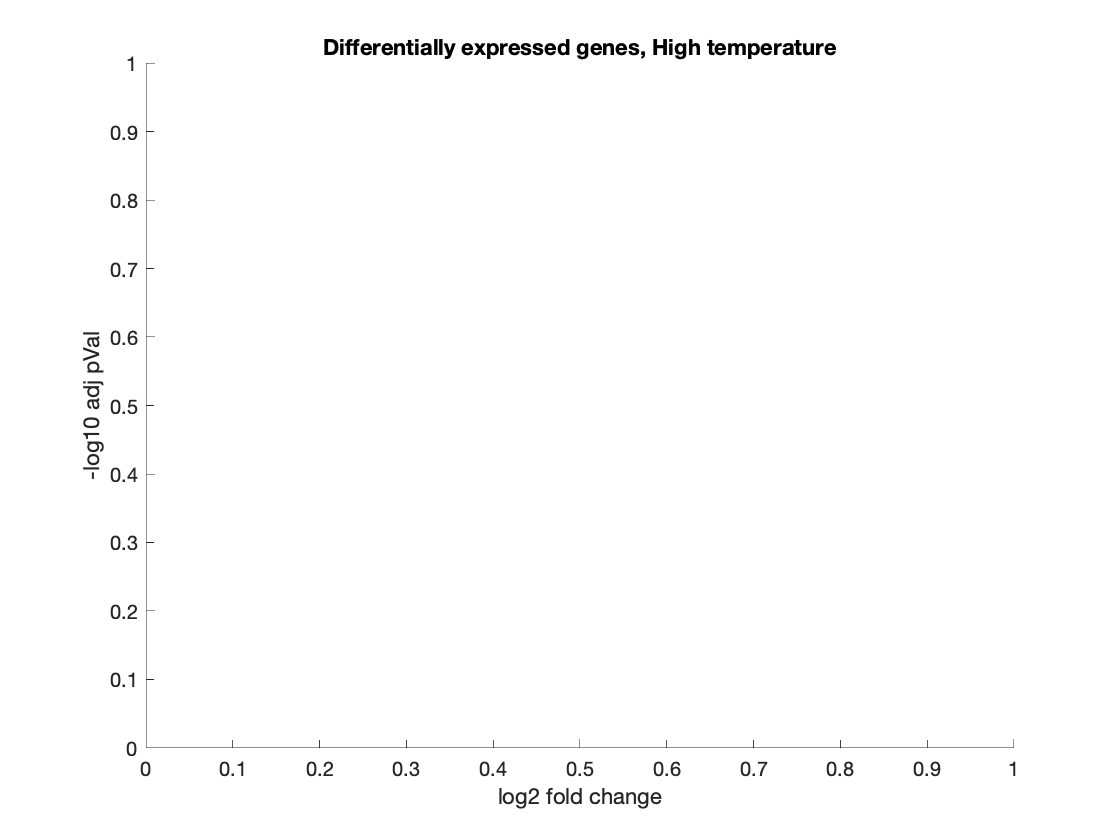

% pick one of the four stress condition that you would like to compare to
% the control
normCountsStress  = normalized_array(:,4:6); % HighTemperature
normCountsref     = normalized_array(:,1:3); % Control

% perform the test for differential expression using a negative binomial model
tLocal = nbintest(normCountsref, normCountsStress, 'VarianceLink', 'LocalRegression');
% correct for multiple testing using the Benjamini Hochberg correction
padj = mafdr(tLocal.pValue, 'BHFDR', true);

% create overview table of the results including the mean for both
% conditions, the resulting log2 fold change and the calculated pValue 
meanRef    = mean(normCountsref, 2);
meanStress = mean(normCountsStress, 2);
log2FC     = log2(meanStress./meanRef);
geneTable  = table(meanRef, meanStress, log2FC, tLocal.pValue, padj);

% add row and column names
geneTable.Properties.RowNames = rnaseq_table.GeneName(all(rnaseq_array, 2),:);
geneTable.Properties.VariableNames = {'Mean_Ref', 'Mean_Stress', 'Log2_FC', 'pVal', 'adjPVal'};
% create a volcano plot for visual inspection of the data
figure
hold on
xlabel('log2 fold change'); ylabel('-log10 adj pVal'); title('Differentially expressed genes, High temperature');

geneTable.color = repmat([0 0 1], height(geneTable), 1);
geneTable.color(geneTable.adjPVal >= 0.01 | abs(geneTable.Log2_FC) <= 2) = {1 0 0};

volcano = scatter(geneTable.Log2_FC, -log10(geneTable.adjPVal), 30, geneTable.color, 'fill');
hold off




Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

Conversion to double from cell is not possible.

**a)** Plot your results in a volcano plot, highlighting with a different color the differentially expressed genes. Explain in some lines how a volcano plot can be interpreted.

**b)** How many down and up regulated genes were obtained?

**c)** How are the results from these plots similar to or different from the results from the PCA plot?